# Understanding Premultiplication vs Postmultiplication

This 'livescript' file helps to understand the diference of rotating axes with the technic of moving frame, which is more intuitive that fixed frame. The cue is the order of multiplication. Moving frame is from left to righ and fixed from right to left.

## Universe RF {U}

Reference frame at the origin [0,0,0] and without any rotation

clear
clc
U=eye(4)

U =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


## Fixed Frame rotations: Premultiplication (Fixed frames)

ZYX

B=trotx(pi/2)*U % Rotation of U pi/2 around x_u axis

B =      1     0     0     0
     0     0    -1     0
     0     1     0     0
     0     0     0     1


C=troty(pi/2)*B % Rotation of B pi/2 around y_u axis

C =      0     1     0     0
     0     0    -1     0
    -1     0     0     0
     0     0     0     1


D=trotz(pi/2)*C % Rotation of C pi/2 around z_u axis

D =      0     0     1     0
     0     1     0     0
    -1     0     0     0
     0     0     0     1


## Moving Frame rotations:] Postmultiplication (Moving frame)

E=U*trotz(pi/2) % Rotation of U pi/2 around z_u axis

E =      0    -1     0     0
     1     0     0     0
     0     0     1     0
     0     0     0     1


F=E*troty(pi/2) % Rotation of B pi/2 around y_e axis

F =      0    -1     0     0
     0     0     1     0
    -1     0     0     0
     0     0     0     1


G=F*trotx(pi/2) % Rotation of C pi/2 around x_f axis

G =      0     0     1     0
     0     1     0     0
    -1     0     0     0
     0     0     0     1


## Visualizing results

## Plotting intermediate result of premultiplication 

subplot (2,4,1) % Open a figure with 2 row x 4 columns
f_1=trplot(U, ... %We plot the reference frame U with all the options
    'frame', 'U', ... 
    'color', 'g',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[30,30]);
title ('Fixed Frame -->','FontWeight','bold','FontSize',16)

subplot (2,4,2)
f_2=trplot(B, ... %We plot the reference frame U with all the options
    'frame', 'B', ... 
    'color', 'b',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
    'view',[30,30]);
title ('B=trotx(pi/2)*U','FontWeight','bold','FontSize',16)

subplot (2,4,3)
f_3=trplot(C, ... %We plot the reference frame U with all the options
    'frame', 'C', ... 
    'color', 'r',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[30,30]);
title ('C=troty(pi/2)*B','FontWeight','bold','FontSize',16)

subplot (2,4,4)
f_4=trplot(D, ... %We plot the reference frame U with all the options
    'frame', 'D', ... 
    'color', 'black',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[30,30]);
title ('D=trotz(pi/2)*C','FontWeight','bold','FontSize',16)


## Plotting intermediate result of postmultiplication

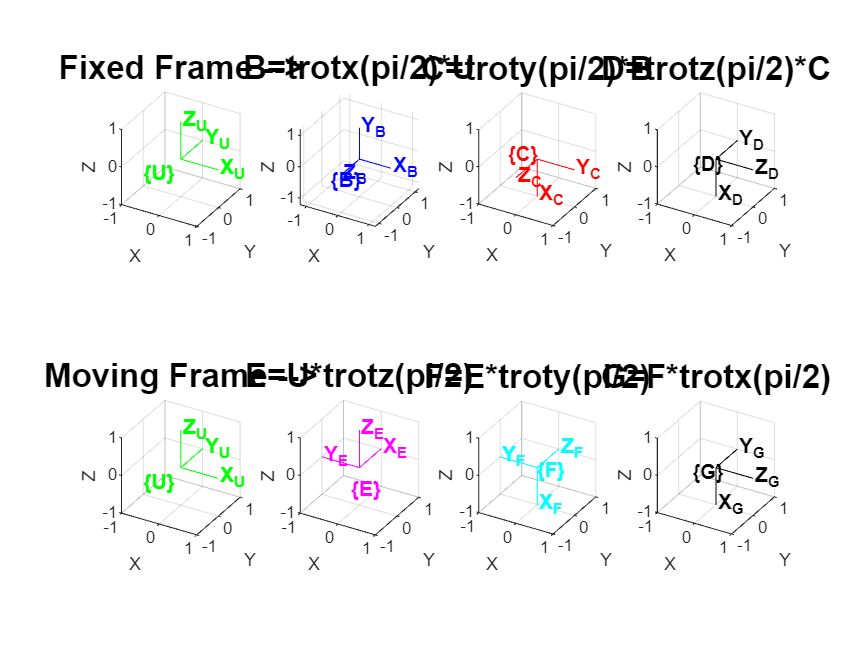

subplot (2,4,5) 
f_5=trplot(U, ... %We plot the reference frame U with all the options
    'frame', 'U', ... 
    'color', 'g',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[30,30]);
title ('Moving Frame -->','FontWeight','bold','FontSize',16)

subplot (2,4,6)
f_6=trplot(E, ... %We plot the reference frame U with all the options
    'frame', 'E', ... 
    'color', 'm',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[30,30]);
title ('E=U*trotz(pi/2)','FontWeight','bold','FontSize',16)

subplot (2,4,7)
f_7=trplot(F, ... %We plot the reference frame U with all the options
    'frame', 'F', ... 
    'color', 'c',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[30,30]);
title ('F=E*troty(pi/2)','FontWeight','bold','FontSize',16)

subplot (2,4,8)
f_8=trplot(G, ... %We plot the reference frame U with all the options
    'frame', 'G', ... 
    'color', 'black',...
    'text_opts', {'FontSize', 10, 'FontWeight', 'bold'},...
    'axis',[-1 1 -1 1 -1 1],...
    'view',[30,30]);
title ('G=F*trotx(pi/2)','FontWeight','bold','FontSize',16)